## *Uncertainty Analysis in Civil Engineering*

# **Assingment 1**

El presente taller tiene como objetivo aplicar los conceptos vistos de análisis preliminar de datos y probabilidad. Los ejercicios propuestos deben ser resueltos de manera numérica y gráfica (si aplica) utilizando Matlab. Posteriormente, se debe realizar un análisis del problema y de los resultados obtenidos, y responder lo que se pregunta. El archivo que contiene las soluciones debe ser cargado al repositorio de GitHub del curso:  

## Problema 1: 

El constructor de un túnel para el sistema de abastecimiento de agua de Bogotá afirmó que la roca era más dura de lo descrito en su contrato con la Empresa de Acueducto y Alcantarillado y que, por lo tanto, se requería más trabajo (tiempo y presupuesto) para construir el túnel de lo anticipado. Una empresa independiente realizó pruebas para verificar la afirmación del contratista. Entre estas pruebas se realizaron ensayos de resistencia a la compresión uniaxial, de los cuales se listan aquí 123 especímenes, en MN/m2.

Realice un histograma y un diagrama de cajas. A partir de los gráficos ¿Existe evidencia para soportar la afirmación del contratista? Justifique su respuesta

%% =========================
% PROBLEMA 1
% Histograma y diagrama de cajas
% =========================

resistencia = [
2.4 22.08 16.8 4.8 21.36 9.12 9.36 3.6 15.36 15.6 6.24 ...
9.84 16.08 30 20.4 12.96 19.2 10.32 15.84 62.4 40.8 4.8 ...
7.2 8.88 14.4 14.88 5.76 18.72 12.48 11.04 8.64 19.2 8.16 ...
18.96 8.64 12 14.88 17.52 12.48 13.44 9.36 11.28 8.88 15.12 ...
9.36 17.28 26.4 4.32 11.28 7.92 13.92 11.76 9.6 8.4 9.84 ...
27.6 6 14.4 8.88 17.04 12.48 9.84 10.8 12.24 12 13.2 ...
11.28 11.76 11.76 8 9.36 15.12 11.52 16.08 10.8 14.64 8.4 ...
13.44 10.56 9.12 13.44 12.72 13.68 11.28 5.52 11.04 12 7.2 ...
8.64 11.76 8.64 7.68 7.68 13.92 6.48 7.2 7.92 9.6 8.64 ...
9.12 12.96 9.36 14.64 9.12 8.88 20.4 17.28 8.64 11.76 7.92 ...
7.68 11.04 12.48 14.4 9.84 9.12 8.4 12 4.8 12.72 9.6 ...
8.64 9.84
];

fprintf('\n================ PROBLEMA 1 ================\n');


================ PROBLEMA 1 ================


fprintf('Numero de datos: %d\n', length(resistencia));

Numero de datos: 123


fprintf('Media: %.3f MN/m^2\n', mean(resistencia));

Media: 12.385 MN/m^2


fprintf('Mediana: %.3f MN/m^2\n', median(resistencia));

Mediana: 11.280 MN/m^2


fprintf('Desviacion estandar: %.3f MN/m^2\n', std(resistencia));

Desviacion estandar: 7.013 MN/m^2


fprintf('Minimo: %.3f MN/m^2\n', min(resistencia));

Minimo: 2.400 MN/m^2


fprintf('Maximo: %.3f MN/m^2\n', max(resistencia));

Maximo: 62.400 MN/m^2


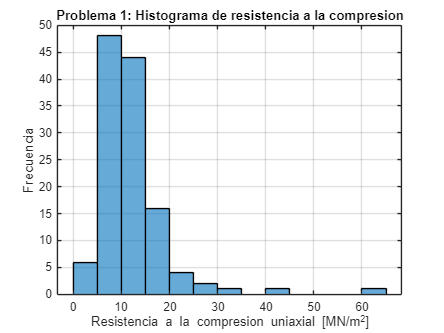


figure;
histogram(resistencia);
title('Problema 1: Histograma de resistencia a la compresion');
xlabel('Resistencia a la compresion uniaxial [MN/m^2]');
ylabel('Frecuencia');
grid on;


figure;
boxplot(resistencia);

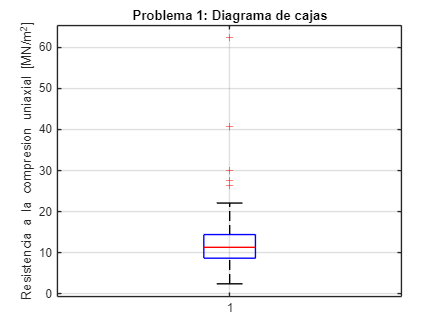

title('Problema 1: Diagrama de cajas');
ylabel('Resistencia a la compresion uniaxial [MN/m^2]');
grid on;

**Análisis**

A partir del histograma y del diagrama de cajas se observa que la distribución de la resistencia a la compresión presenta una **asimetría positiva**, evidenciada por el hecho de que la media (12.385 MN/m²) es mayor que la mediana (11.280 MN/m²). Esto indica la presencia de valores altos que están desplazando el promedio.

La mayoría de los datos se concentra aproximadamente entre 8 y 15 MN/m², lo que sugiere que este es el rango típico de resistencia del material. Sin embargo, se identifican valores considerablemente altos, como 30.000, 40.800 y 62.400 MN/m², los cuales pueden considerarse **valores atípicos**.

Estos resultados indican que, aunque existen muestras con resistencia significativamente mayor, estas no representan el comportamiento general del material. Por lo tanto, la evidencia **solo soporta parcialmente la afirmación del contratista**, ya que la mayor parte de la roca no presenta una resistencia superior a la esperada.

.

## Problema 2: 

El análisis de datos de tormentas es esencial para predecir los riesgos de inundación en áreas urbanas. A continuación se presentan las profundidades máximas de lluvia registradas en la Universidad Nacional de Colombia, para duraciones que varían desde 5 minutos hasta 3 horas, correspondientes a los años 1974-1987.

Calcule la media (x), la desviación estándar (S) y el coeficiente de asimetría (g1) para cada duración. ¿Existen patrones en el crecimiento de estas estadísticas con el aumento de la duración? Comente sobre los resultados y la relevancia física para las características de las tormentas.

%% =========================
% PROBLEMA 2
% Media, desviacion estandar y asimetria
% =========================

duracion = [5 10 20 30 40 50 60 120 180];

lluvia = [
12.1 19.5 28.8 30.5 32.4 35.5 38.7 48 51.6;
10.1 14.9 26.7 31.2 34.7 38.2 40.2 55 56;
17.9 20 31.1 37.2 41.1 51 55.7 67.1 80.6;
20 32.6 52.6 72.4 90.1 108.8 118.9 146.5 157.3;
5.1 13.6 16 21.3 24.1 24.6 25 40.7 49.9;
20.5 26.1 36.3 46.1 49.3 50.3 55.6 65.2 90.1;
10 15.7 20.9 25 30.5 38 40.1 58 63.8;
12 27.9 47.9 56 70 80 89.4 106.9 114.2;
10 14.4 20 23.3 25.1 26.4 27.2 34.3 41.2;
10 12.1 17.3 19.2 22.1 27.3 32.7 54.4 66.5;
20.1 32.8 60 65.7 76.1 92.8 105.7 122.3 122.3;
7.6 8.1 13 16.5 21.6 25.3 25.3 27 32.3;
8.7 11.7 20 22.9 26.1 26.3 27.6 41.1 56.7;
24.6 36.7 56.7 73.9 93.9 110.1 128.5 180.8 188.7
];

media_lluvia = mean(lluvia);
desv_lluvia = std(lluvia);
asim_lluvia = skewness(lluvia);

tabla_p2 = table(duracion', media_lluvia', desv_lluvia', asim_lluvia', ...
    'VariableNames', {'Duracion_min', 'Media', 'Desviacion_Estandar', 'Asimetria'});

fprintf('\n================ PROBLEMA 2 ================\n');


================ PROBLEMA 2 ================


disp(tabla_p2);

    Duracion_min    Media     Desviacion_Estandar    Asimetria
    ____________    ______    ___________________    _________

          5         13.479          5.9375            0.49755 
         10         20.436          9.1502            0.48464 
         20          31.95          16.108            0.59647 
         30         38.657          20.445            0.68269 
         40         45.507          25.995            0.84662 
         50         52.471          31.744            0.87951 
         60           57.9          36.828            0.89182 
        120         74.807          46.283             1.1306 
        180         83.657          46.179             1.0602 



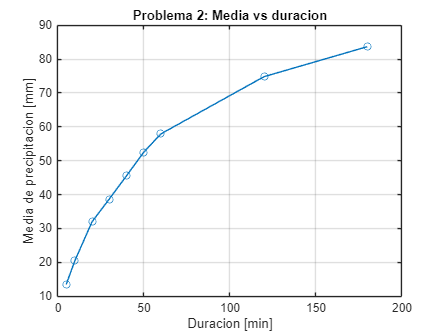


figure;
plot(duracion, media_lluvia, '-o');
title('Problema 2: Media vs duracion');
xlabel('Duracion [min]');
ylabel('Media de precipitacion [mm]');
grid on;

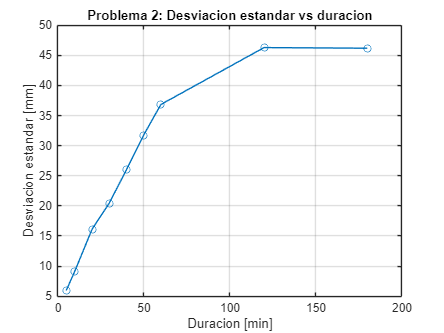


figure;
plot(duracion, desv_lluvia, '-o');
title('Problema 2: Desviacion estandar vs duracion');
xlabel('Duracion [min]');
ylabel('Desviacion estandar [mm]');
grid on;

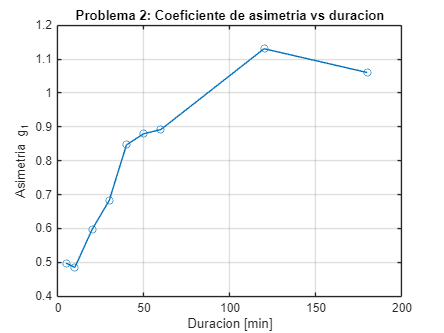


figure;
plot(duracion, asim_lluvia, '-o');
title('Problema 2: Coeficiente de asimetria vs duracion');
xlabel('Duracion [min]');
ylabel('Asimetria g_1');
grid on;

**Análisis**

.Los resultados muestran que la **media de la precipitación aumenta con la duración**, pasando de 13.479 mm para 5 minutos hasta 83.657 mm para 180 minutos. Este comportamiento es consistente, ya que una mayor duración implica una mayor acumulación de lluvia.

La **desviación estándar también aumenta con la duración**, lo que indica que las tormentas más largas presentan mayor variabilidad entre eventos. Esto sugiere que los fenómenos de larga duración están influenciados por condiciones más variables y complejas.

El coeficiente de **asimetría es positivo en todas las duraciones**, lo que indica la presencia de eventos extremos con altas intensidades. Además, esta asimetría tiende a incrementarse con la duración, lo que refleja que las tormentas prolongadas tienen mayor probabilidad de presentar valores extremos.

En conjunto, los resultados muestran que las tormentas largas no solo acumulan más lluvia, sino que también presentan mayor incertidumbre y mayor influencia de eventos extremos, lo cual es relevante para el diseño hidráulico.

## Problema 3: 

El daño provocado por los huracanes es una de las grandes preocupaciones para los ingenieros civiles. Se anexan las frecuencias de huracanes que afectan a la isla de Cuba cada año durante un periodo de 69 años. Dibuje un diagrama de líneas y analice su forma con base en el fenómeno estudiado.

%% =========================
% PROBLEMA 3
% Diagrama de lineas
% =========================

num_huracanes = 0:9;
frecuencia = [1 6 10 16 19 5 7 3 1 1];

fprintf('\n================ PROBLEMA 3 ================\n');


================ PROBLEMA 3 ================


tabla_p3 = table(num_huracanes', frecuencia', ...
    'VariableNames', {'Numero_de_huracanes', 'Frecuencia'});
disp(tabla_p3);

    Numero_de_huracanes    Frecuencia
    ___________________    __________

             0                  1    
             1                  6    
             2                 10    
             3                 16    
             4                 19    
             5                  5    
             6                  7    
             7                  3    
             8                  1    
             9                  1    



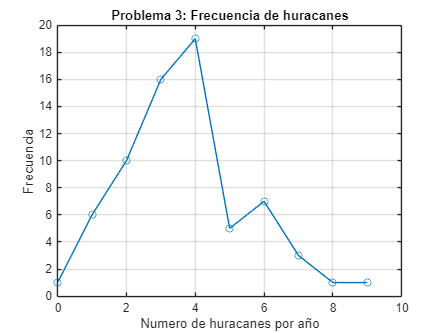


figure;
plot(num_huracanes, frecuencia, '-o');
title('Problema 3: Frecuencia de huracanes');
xlabel('Numero de huracanes por año');
ylabel('Frecuencia');
grid on;

**Análisis**

.El análisis de la frecuencia de huracanes muestra una distribución **discreta y unimodal**, donde el valor más frecuente es de 4 huracanes por año, con una frecuencia de 19. La frecuencia aumenta progresivamente desde 0 hasta este valor y luego disminuye hacia valores mayores.

Esto indica que los valores bajos y moderados son los más comunes, mientras que los eventos extremos, como 8 o 9 huracanes, son poco frecuentes. Este comportamiento es característico de fenómenos naturales aleatorios.

La forma de la distribución es consistente con modelos probabilísticos como la distribución de Poisson, donde existe un valor más probable y una menor frecuencia hacia los extremos.

En términos prácticos, esto indica que, aunque existe un comportamiento relativamente estable en la ocurrencia de huracanes, deben considerarse los eventos extremos en la evaluación del riesgo.

## Problema 4: 

Un componente estructural tiene soldaduras que deben ser inspeccionadas en busca de defectos. Según registros pasados, la empresa ha encontrado que la probabilidad de detectar un defecto en una soldadura, P(DF), es proporcional a su longitud L, es decir, P(DF) = 0.2L. Si se detectan defectos en la sección A1, la probabilidad de detectarlos en la sección A2 es 3 veces el valor original. Si se detectan defectos en la sección A, la probabilidad de detectarlos en la sección B es 2 veces mayor. Sean DF1, DF2, DA, DB y D los eventos de que se detecten defectos en A1, A2, A, B y en todo el elemento estructural, respectivamente. Calcule las siguientes probabilidades.

- P(FA)

- P(F)

- La probabilidad de que se encuentren defectos solo en A, dado que el componente tiene defectos que son detectados.

- Determine la probabilidad de que se encuentren defectos solo en la sección B, dado que el componente tiene defectos que son detectados.

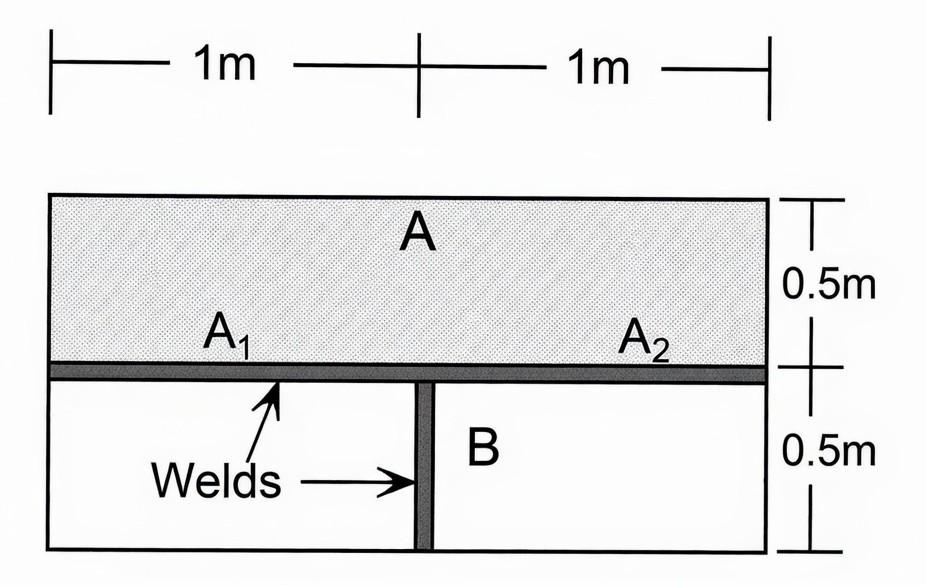

%% =========================
% PROBLEMA 4
% Probabilidades en soldaduras
% =========================

% Longitudes de las secciones
L_A1 = 1;
L_A2 = 1;
L_A = 2;
L_B = 0.5;

% Probabilidad base: P(DF) = 0.2 L
P_DF1 = 0.2 * L_A1;
P_DF2_original = 0.2 * L_A2;
P_DA = 0.2 * L_A;
P_DB_original = 0.2 * L_B;

% Condiciones dadas
% Si hay defectos en A1, en A2 es 3 veces el valor original
P_DF2_cond_DF1 = 3 * P_DF2_original;

% Si hay defectos en A, en B es 2 veces el valor original
P_DB_cond_DA = 2 * P_DB_original;

% Probabilidad de falla en A
P_FA = P_DF1 + P_DF2_cond_DF1 - P_DF1 * P_DF2_cond_DF1;

% Probabilidad de falla en todo el componente
P_F = P_DA + P_DB_cond_DA - P_DA * P_DB_cond_DA;

% Probabilidad de solo A dado que hay defectos
P_solo_A = P_DA * (1 - P_DB_cond_DA);
P_solo_A_dado_D = P_solo_A / P_F;

% Probabilidad de solo B dado que hay defectos
P_solo_B = P_DB_cond_DA * (1 - P_DA);
P_solo_B_dado_D = P_solo_B / P_F;

fprintf('\n================ PROBLEMA 4 ================\n');


================ PROBLEMA 4 ================


fprintf('P(FA) = %.4f\n', P_FA);

P(FA) = 0.6800


fprintf('P(F) = %.4f\n', P_F);

P(F) = 0.5200


fprintf('P(solo A | D) = %.4f\n', P_solo_A_dado_D);

P(solo A | D) = 0.6154


fprintf('P(solo B | D) = %.4f\n', P_solo_B_dado_D);

P(solo B | D) = 0.2308


**Análisis**

.Los resultados muestran que la probabilidad de detectar defectos en la sección A es de 0.6800, lo que indica una alta probabilidad de presencia de defectos en esta zona. Por otro lado, la probabilidad de encontrar defectos en todo el componente es de 0.5200.

Condicionado a que se detecten defectos, la probabilidad de que estos se encuentren únicamente en la sección A es de 0.6154, mientras que para la sección B es de 0.2308. Esto indica que la sección A tiene una mayor contribución a la detección de defectos.

Estos resultados sugieren que la sección A es más crítica en términos de calidad estructural, ya que presenta una mayor probabilidad de fallas en comparación con la sección B.

## Problema 5: 

Las tuberías de concreto reforzado se someten a pruebas de fugas a una presión específica antes de su envío. Un tubo debe fallar (F) si se identifica una fuga (L). De manera similar, un tubo no debe fallar (F^c) si la prueba indica que no hay fugas (L^c). Sin embargo, es posible que un tubo que no tiene fugas falle la prueba.

Los registros anteriores indican que:

- P(L^c) = 0.95 (Probabilidad de no tener fugas)

- P(F|L) = 0.98 (Probabilidad de fallar la prueba dado que hay una fuga)

- P(F|L^c) = 0.03 (Probabilidad de fallar la prueba dado que no hay fugas / Falso positivo)

- Utilice el teorema de la probabilidad total para calcular la probabilidad de falla, P(F).

- Utilice el teorema de Bayes para calcular la probabilidad de una fuga dado que el tubo falla, P(L|F), y la probabilidad de que no haya fugas dado que el tubo no falla, P(L^c|F^c).

%% =========================
% PROBLEMA 5
% Probabilidad total y Bayes
% =========================

P_Lc = 0.95;
P_L = 1 - P_Lc;

P_F_dado_L = 0.98;
P_F_dado_Lc = 0.03;

% Probabilidad total de falla
P_F = P_F_dado_L * P_L + P_F_dado_Lc * P_Lc;

% Bayes: probabilidad de fuga dado que falla
P_L_dado_F = (P_F_dado_L * P_L) / P_F;

% Probabilidad de no falla
P_Fc = 1 - P_F;

% Probabilidades complementarias
P_Fc_dado_Lc = 1 - P_F_dado_Lc;

% Bayes: probabilidad de no fuga dado que no falla
P_Lc_dado_Fc = (P_Fc_dado_Lc * P_Lc) / P_Fc;

fprintf('\n================ PROBLEMA 5 ================\n');


================ PROBLEMA 5 ================


fprintf('P(F) = %.4f\n', P_F);

P(F) = 0.0775


fprintf('P(L | F) = %.4f\n', P_L_dado_F);

P(L | F) = 0.6323


fprintf('P(Lc | Fc) = %.4f\n', P_Lc_dado_Fc);

P(Lc | Fc) = 0.9989


**Análisis**

.La probabilidad total de que el tubo falle la prueba es de 0.0775, lo que corresponde a aproximadamente un 7.75 %. Esto indica que la ocurrencia de fallas es relativamente baja.

Sin embargo, la probabilidad de que exista una fuga dado que el tubo falla es de 0.6323, lo que indica que no todas las fallas están asociadas a fugas reales, evidenciando la presencia de falsos positivos en la prueba.

Por otro lado, la probabilidad de que no haya fuga dado que el tubo no falla es de 0.9989, lo que demuestra que la prueba es altamente confiable cuando el resultado es negativo.

En general, el sistema de prueba es efectivo, aunque presenta cierta incertidumbre cuando detecta fallas.

## Problema 6: 

El suministro de agua para una ciudad C proviene de 2 fuentes, A y B. Las tuberías transportan el agua hacia C (ver figura). Suponga que cualquiera de las dos fuentes puede abastecer a C con suficiente agua por sí sola.

- Encuentre una expresión para la escasez (desabastecimiento) de agua en C.

- Encuentre una expresión para la no escasez (suministro exitoso) en C.

- Calcule la probabilidad de escasez si se asume que las probabilidades de falla de las tuberías 1, 2 y 3 son independientes y son iguales a 0.01, 0.005 y 0.02, respectivamente.

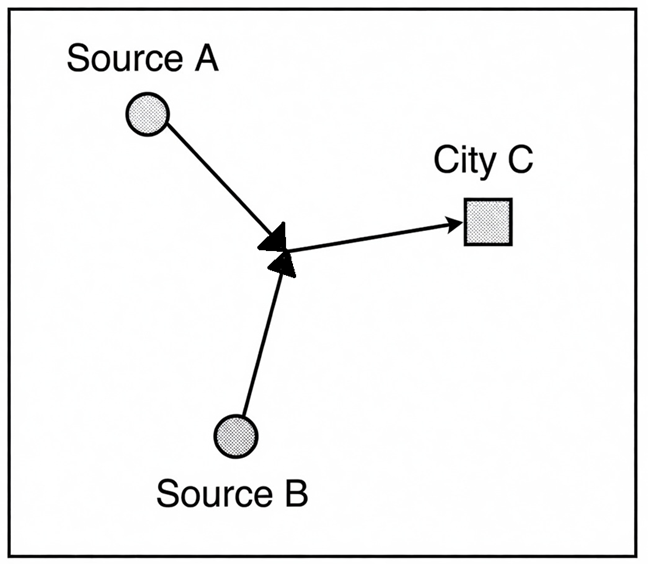

%% =========================
% PROBLEMA 6
% Sistema de abastecimiento
% =========================

% Probabilidades de falla de las tuberias
P_f1 = 0.01;
P_f2 = 0.005;
P_f3 = 0.02;

% Suposicion:
% Tuberia 1 conecta Fuente A con nodo comun
% Tuberia 2 conecta Fuente B con nodo comun
% Tuberia 3 conecta nodo comun con ciudad C
%
% Hay escasez si:
% falla la tuberia 3, o si fallan al mismo tiempo las tuberias 1 y 2.

P_no_f1 = 1 - P_f1;
P_no_f2 = 1 - P_f2;
P_no_f3 = 1 - P_f3;

P_escasez = P_f3 + (P_f1 * P_f2 * P_no_f3);

P_no_escasez = 1 - P_escasez;

fprintf('\n================ PROBLEMA 6 ================\n');


================ PROBLEMA 6 ================


fprintf('Expresion de escasez: E = F3 U (F1 interseccion F2 interseccion F3c)\n');

Expresion de escasez: E = F3 U (F1 interseccion F2 interseccion F3c)


fprintf('Expresion de no escasez: Ec = F3c interseccion (F1c U F2c)\n');

Expresion de no escasez: Ec = F3c interseccion (F1c U F2c)


fprintf('P(escasez) = %.6f\n', P_escasez);

P(escasez) = 0.020049


fprintf('P(no escasez) = %.6f\n', P_no_escasez);

P(no escasez) = 0.979951


**Análisis**

.La probabilidad de escasez de agua en la ciudad es de 0.020049, aproximadamente un 2 %, mientras que la probabilidad de no escasez es cercana al 98 %.

Esto indica que el sistema de abastecimiento es altamente confiable, principalmente debido a la existencia de dos fuentes de suministro que generan redundancia en el sistema.

La escasez ocurre en situaciones específicas, como la falla de la tubería principal hacia la ciudad o la falla simultánea de las dos tuberías de alimentación.

En consecuencia, el sistema presenta una alta resiliencia frente a fallas individuales, lo cual es deseable en sistemas de abastecimiento de agua.

## Problema 7: 

Las centrales hidroeléctricas de pasada (a filo de Agua) convierten la energía potencial natural del agua superficial de una corriente en energía eléctrica. La capacidad de la planta depende del caudal natural del río, el cual generalmente varía durante el año de acuerdo con la estación y el régimen de precipitaciones.

Suponga que el caudal de diseño de una central eléctrica dada, digamos Q_D, es el caudal natural que es superado durante 274 días al año en promedio. En otros momentos, cuando el caudal del río es menor que el caudal de diseño, la planta es, sin embargo, capaz de producir algo de energía si el caudal no es menor que Q_0.

Además, durante las crecidas (inundaciones) no es posible conducir agua a la planta debido a la sedimentación, lo cual ocurre cuando el caudal natural del río Q excede Q_1.

Preguntas:

(a) Si Pr[Q < Q_0] = 0.1 y Pr[Q > Q_1] = 0.05, ¿durante cuántos días en un año la planta será incapaz de suministrar energía eléctrica?

(b) ¿Cuál es la probabilidad de que la planta funcione a plena capacidad?

(c) ¿Cuál es la probabilidad de que la planta cumpla con su objetivo mínimo?

*Nota: **Q_0 < Q_D < Q_1*

%% =========================
% PROBLEMA 7
% Central hidroelectrica
% =========================

P_Q_menor_Q0 = 0.10;
P_Q_mayor_Q1 = 0.05;

% La planta no suministra energia si Q < Q0 o Q > Q1
P_no_funciona = P_Q_menor_Q0 + P_Q_mayor_Q1;

dias_no_funciona = P_no_funciona * 365;

% QD es superado durante 274 dias al año
P_plena_capacidad = 274 / 365;

% Cumple objetivo minimo si Q >= Q0 y Q <= Q1
P_objetivo_minimo = 1 - P_no_funciona;

fprintf('\n================ PROBLEMA 7 ================\n');


================ PROBLEMA 7 ================


fprintf('P(no funciona) = %.4f\n', P_no_funciona);

P(no funciona) = 0.1500


fprintf('Dias sin suministrar energia = %.2f dias\n', dias_no_funciona);

Dias sin suministrar energia = 54.75 dias


fprintf('P(plena capacidad) = %.4f\n', P_plena_capacidad);

P(plena capacidad) = 0.7507


fprintf('P(cumple objetivo minimo) = %.4f\n', P_objetivo_minimo);

P(cumple objetivo minimo) = 0.8500


**Análisis**

La probabilidad de que la planta no funcione es de 0.15, lo que equivale a aproximadamente 54.75 días al año sin generación de energía. Esto se debe a condiciones de caudal muy bajo o excesivamente alto.

La probabilidad de operar a plena capacidad es de 0.7507, lo que indica que durante la mayor parte del año el caudal es suficiente para alcanzar el nivel de diseño.

Adicionalmente, la probabilidad de cumplir con el objetivo mínimo de operación es de 0.85, lo que muestra que la planta puede generar energía, al menos parcialmente, en la mayoría de las condiciones.

Estos resultados reflejan un buen desempeño del sistema, aunque evidencian la influencia de la variabilidad del caudal en la operación de la planta.